
                                        First-order                     Norm of 
 Iteration  Func-count   ||f(x)||^2      optimality       Lambda           step
     0           3      1.66647e-29        4.32e-14         0.01

Equation solved at initial point.

fsolve completed because the vector of function values at the initial
point is near zero as measured by the value of the function tolerance,
and the problem appears regular as measured by the gradient.

<stopping criteria details>


fval = 1.0e-14 *

   -0.1554
    0.3775



                                        First-order                     Norm of 
 Iteration  Func-count   ||f(x)||^2      optimality       Lambda           step
     0           3      1.66647e-29        4.32e-14         0.01

Equation solved at initial point.

fsolve completed because the vector of function values at the initial
point is near zero as measured by the value of the function tolerance,
and the problem appears regular as measured by the gradient.

<stopping criteria details>


fval = 1.0e-14 *

   -0.1554
    0.3775


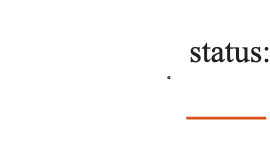

% Use one row directly from anisotropy_clean (table)
nD = 200;   %#ok<NASGU>
Nseg = 8;   %#ok<NASGU>

i = 2;

a1 = anisotropy_filter.a1(i);
a2 = anisotropy_filter.a2(i);
a3 = anisotropy_filter.a3(i);
eps_bist = anisotropy_filter.eps_bist(i);
eta_row  = anisotropy_filter.eta_val(i); %#ok<NASGU>
beta_row = anisotropy_filter.beta(i);

%eps_bist = 0.210*0.98*0.955;
eps_bist = 0.96*eps_bist;

% Convert (a1,a2,a3,eps_bist) -> edge scale factors
lam3 = 1 + eps_bist;
lam1 = (sin(a1)/sin(a3)) * lam3;
lam2 = (sin(a2)/sin(a3)) * lam3;

edgeLen = 15;
l1 = edgeLen * 0.85;
l4 = edgeLen * 0.05;
t = edgeLen * 0.015;

% Convert to edge lengths
L1 = lam1 * edgeLen;   % |q2-q3|
L2 = lam2 * edgeLen;   % |q1-q3|
L3 = lam3 * edgeLen;   % |q1-q2|

% Build triangle coordinates
q1 = [0, 0, 0];
q2 = [0, -L3, 0];
q3_y = (L1^2 - L2^2 - L3^2) / (2*L3);
q3_x = -sqrt(max(L2^2 - q3_y^2, 0));
q3 = [q3_x, q3_y, 0];

t_sel = edgeLen * 0.015;

[strain_bist, bistability, info_bist] = bistability_analysis( ...
    l1, l4, beta_row, t_sel, edgeLen, q1, q2, q3, true);


% [E_sel, alpha_sel] = deform_triangle_anisotropic( ...
%     q1, q2, q3, edgeLen, l1, l4, beta_row, t_sel, nD, Nseg, true);
